# 1.7. Механика систем частиц

#### [Положение центра масс (ЦМ)](https://ru.wikipedia.org/wiki/Центр_масс)

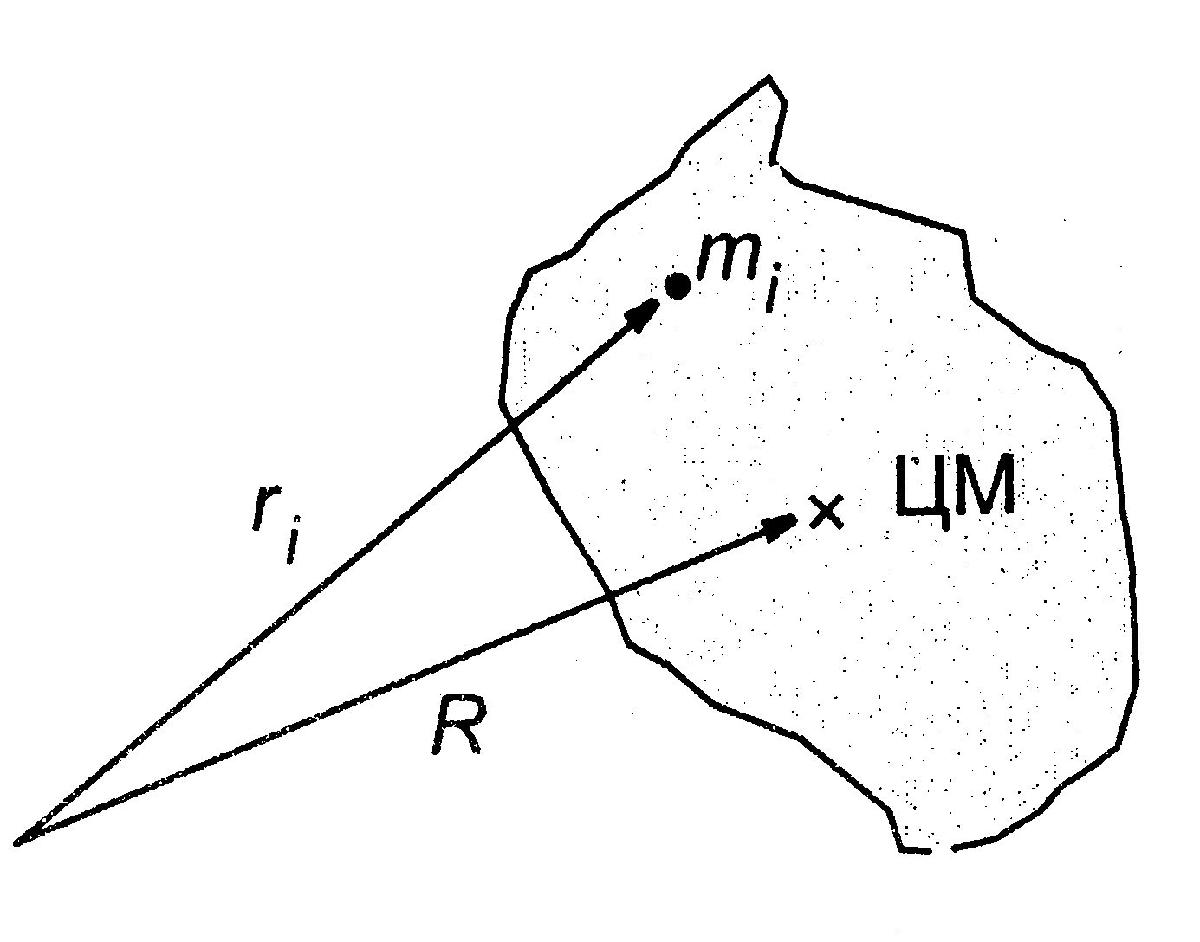

clear
syms R m(i) r(i) M
R==symsum(m*r)/M, M==symsum(m(i))

$$ans(i) = R=\frac{\sum_{i}m\left(i\right)\,r\left(i\right)}{M}$$

$$ans = M=\sum_{i}m\left(i\right)$$

#### [Закон движения центра масс](https://ru.wikipedia.org/wiki/Теорема_о_движении_центра_масс_системы)


$$m\;\ddot{R} =F^{\mathrm{cxt}}$$



$$F^{\mathrm{cxt}} =\mathrm{внешняя}\;\mathrm{сила}=\sum_i f_i$$


syms m t R F_cxt f(i) d(f,x,n)
m*d(R,t,2)==F_cxt

$$ans = m\,d\left(R,t,2\right)=F_{\mathrm{cxt}}$$

F_cxt==symsum(f)  % внешняя сила

$$ans(i) = F_{\mathrm{cxt}}=\sum_{i}f\left(i\right)$$

#### Две частицы; приведенная масса и закон движения 

syms mu m1 m2
mu==m1*m2/(m1+m2)

$$ans = \mu =\frac{m_{1}\,m_{2}}{m_{1}+m_{2}}$$

syms mu t r1 r2 F_cxt1 F_cxt2 F_in1
mu*(d(r1,t,2)-d(r2,t,2))==F_in1+mu*(F_cxt1/m1-F_cxt2/m2)

$$ans = \mu \,\left(d\left(r_{1},t,2\right)-d\left(r_{2},t,2\right)\right)=F_{\mathrm{in1}}+\mu \,\left(\frac{F_{\mathrm{cxt1}}}{m_{1}}-\frac{F_{\mathrm{cxt2}}}{m_{2}}\right)$$

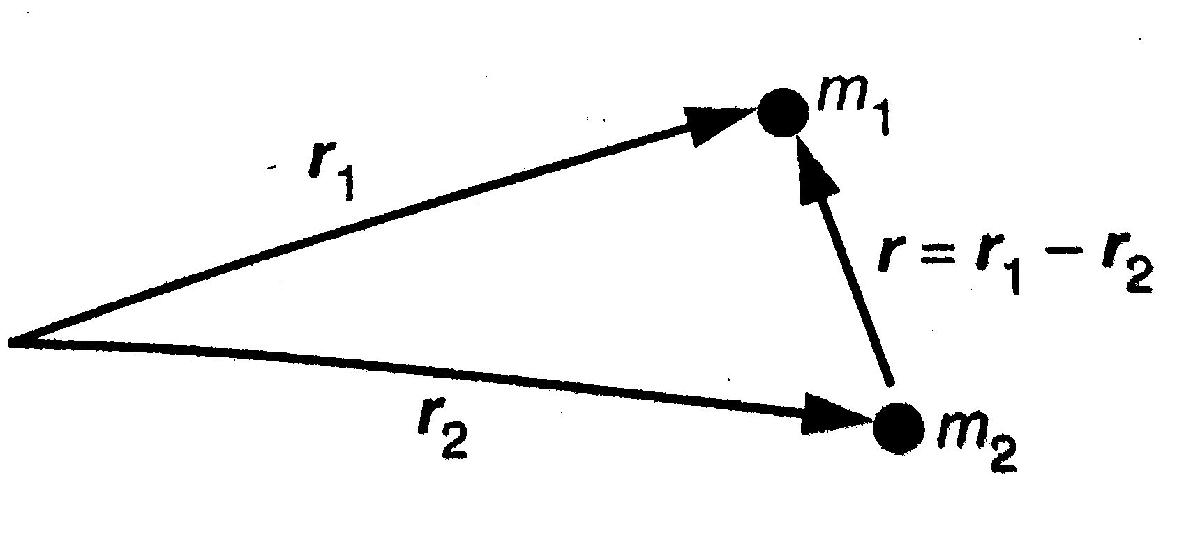

#### [Законы моментов](https://ru.wikipedia.org/wiki/Момент_импульса) 


$$L^p =\sum_i r_i^p \times m_{i\;} {\dot{r_i } }^p$$


clear
syms L_p r_p(i) m(i) rd_p(i) vprod(x,y) t d(f,x,n)
% rd_p = diff(r_p,t)
L_p==symsum(vprod(r_p,m*d(r_p(i),t,1)))

$$ans = L_{p}=\sum_{t}\mathrm{vprod}\left(r_{p}\left(i\right),m\left(i\right)\,d\left(r_{p}\left(i\right),t,1\right)\right)$$


$$\mathit{\mathbf{L}}={\mathit{\mathbf{L}}}^* +\mathit{\mathbf{R}}\times m\;\dot{\mathit{\mathbf{R}}}$$


syms L L1 R m Rd
L==L1+vprod(R,m*d(R,t,1))

$$ans = L=L_{1}+\mathrm{vprod}\left(R,m\,d\left(R,t,1\right)\right)$$

% L1 = L* - угловой момент относительно центра масс


$$\frac{d}{\mathrm{dt}}{\mathit{\mathbf{L}}}^p ={\mathit{\mathbf{M}}}^p -m\;\left(\mathit{\mathbf{R}}-{\mathit{\mathbf{r}}}_p \right)\times {\ddot{r} }_p$$


syms L_p M_p m R r2d_p r_p
% r2d_p = diff(r_p,t,2)
d(L_p,t,1)==M_p-m*vprod((R-r_p),d(r_p,t,2))

$$ans = d\left(L_{p},t,1\right)=M_{p}-m\,\mathrm{vprod}\left(R-r_{p},d\left(r_{p},t,2\right)\right)$$

В частности, если

1. Точка P движется с постоянной скоростью или

2. P = центр масс или

3. P - точка, движ с ускорением отн ЦМ


$$\frac{d}{\mathrm{dt}}{\mathit{\mathbf{L}}}^p ={\mathit{\mathbf{M}}}^p$$


d(L_p,t,1)==M_p

$$ans = d\left(L_{p},t,1\right)=M_{p}$$

#### [Кинетическая энергия](https://ru.wikipedia.org/wiki/Кинетическая_энергия)

clear
syms E_k m(i) v(i)
E_k==1/2*symsum(m*v^2)

$$ans(i) = E_{k}=\frac{\sum_{i}m\left(i\right)\,{v\left(i\right)}^{2}}{2}$$

#### [Теорема Кёнига](https://ru.wikipedia.org/wiki/%D0%A2%D0%B5%D0%BE%D1%80%D0%B5%D0%BC%D0%B0_%D0%9A%D1%91%D0%BD%D0%B8%D0%B3%D0%B0_(%D0%BC%D0%B5%D1%85%D0%B0%D0%BD%D0%B8%D0%BA%D0%B0)) 


$$E_k ={E_k }^* +\frac{1}{2}m\;{\dot{R} }^2$$


syms E_k E_k1 t R d(f,x,n)
% Rd = diff(R,t)
E_k==E_k1+1/2*m*d(R,t,1)^2 

$$ans(i) = E_{k}=\frac{m\left(i\right)\,{d\left(R,t,1\right)}^{2}}{2}+E_{\mathrm{k1}}$$

% E_k1 = E*_k - кинетическая энергия в системе центра масс

#### [Консервативная сила](https://ru.wikipedia.org/wiki/%D0%9A%D0%BE%D0%BD%D1%81%D0%B5%D1%80%D0%B2%D0%B0%D1%82%D0%B8%D0%B2%D0%BD%D1%8B%D0%B5_%D1%81%D0%B8%D0%BB%D1%8B) 


$$F=-\mathrm{grad}\;E_p =-\nabla E_p$$


syms E E_p E_k grad(x) nabla(x) F const
% grad(x) = ∇x
F==-grad(E_p)==-nabla(E_p)

$$ans = \left(F=-\mathrm{grad}\left(E_{p}\right)\right)=-\mathrm{nabla}\left(E_{p}\right)$$

E==E_p+E_k == const

$$ans = \left(\text{E}=E_{k}+E_{p}\right)=\mathrm{const}$$

#### [Закон сохранения импульса](https://ru.wikipedia.org/wiki/%D0%97%D0%B0%D0%BA%D0%BE%D0%BD_%D1%81%D0%BE%D1%85%D1%80%D0%B0%D0%BD%D0%B5%D0%BD%D0%B8%D1%8F_%D0%B8%D0%BC%D0%BF%D1%83%D0%BB%D1%8C%D1%81%D0%B0) в изолированной системе


$$P_{\mathrm{poln}} =\sum_i m_i {\mathit{\mathbf{v}}}_i =m\;\dot{\mathit{\mathbf{R}}} =\mathrm{const}$$


syms P_poln m(i) v(i) Rd const M
P_poln==symsum(m(i)*v(i))==M*d(R,t,1)==const

$$ans = \left(\left(P_{\mathrm{poln}}=\sum_{i}m\left(i\right)\,v\left(i\right)\right)=M\,d\left(R,t,1\right)\right)=\mathrm{const}$$